## Leman FENG TP1

## 1.

This function is not convex. Because it's not convex along one axis.

Minimum point is (1,1)


$$\nabla J = [2(x-1)+40(x^2-y)x, 20(y-x^2)]$$



$$\nabla^2 J = 
\pmatrix{
2+40(3x^2-y) & -40x \cr -40x & 20 
}$$


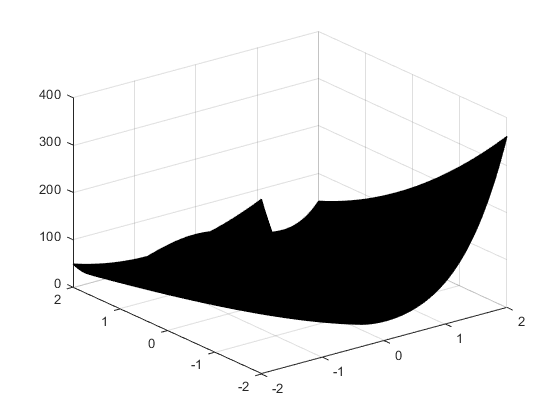

[X,Y] = meshgrid(-2:0.01:2,-2:0.01:2);
J = (X-1).^2 + 10*(X.*X - Y).^2;
figure(1);
surf(X,Y,J);

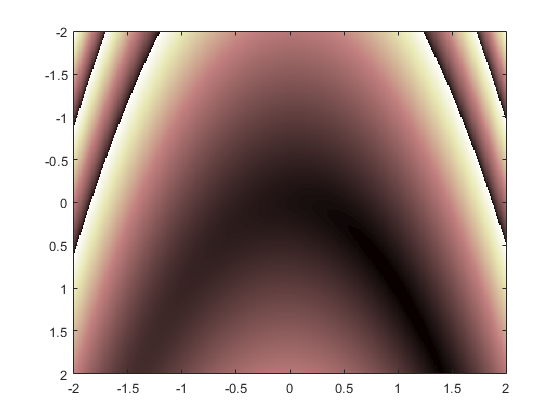

figure(2);
imagesc([-2,2],[-2,2],J);
colormap([pink;pink;pink]);

j = @(x) (x(1)-1)^2 + 10*(x(1)^2-x(2))^2;
g = @(x) [2*(x(1)-1)+40*(x(1)^2-x(2))*x(1);20*(x(2)-x(1)^2)];
h = @(x) [2+40*(3*x(1)^2-x(2)),-40*x(1);-40*x(1),20];
error = @(x) sqrt(sum((x-[1;1]).^2));

## 2

[x,t] = newton_search([-1;1],[1;0],g,h)

x =    -0.9472
    1.0000


t = 0.0528

Comment: newton in this direction merely avanced.

## 3.1

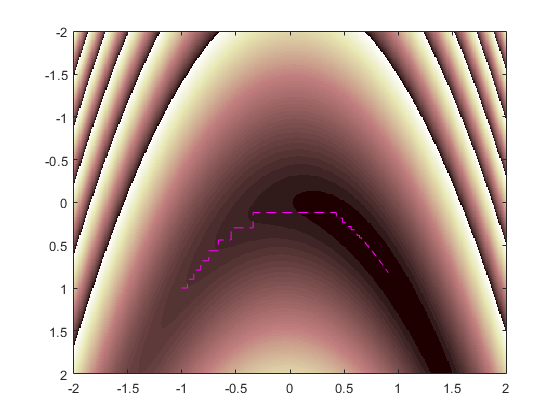

n=100;
figure(3);
imagesc([-2,2],[-2,2],J);
cmap = pink;
colormap([cmap;cmap;cmap;cmap;cmap;cmap]);
hold on;
er1 = zeros(1,n);
for k=1:1
    d=[1;0];
    %x=[rand*2-1;rand*2-1];
    x=[-1;1];
    traj=zeros(2,n);
    traj(:,1)=x;
    er1(1)=error(x);
    for i = 1:n-1
        [x,t] = newton_search(x,d,g,h);
        traj(:,i+1)=x;
        d=circshift(d,1);
        er1(i+1)=error(x);
    end
    plot(traj(1,:),traj(2,:),'--m');
end

## 3.2

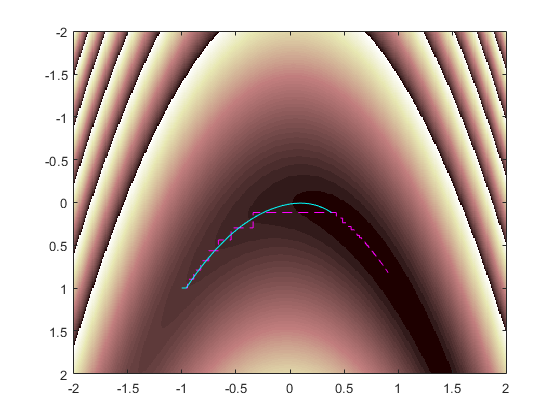

%figure(4);
%imagesc([-2,2],[-2,2],J);
%colormap([pink;pink;pink;pink;pink;pink]);
hold on;
er2 = zeros(1,n);
for k=1:1
    %x=[rand*2-1;rand*2-1];
    x=[-1;1];
    traj=zeros(2,n);
    traj(:,1)=x;
    er2(1)=error(x);
    for i = 1:n-1
        x = gradient_const(x,g,0.01);
        traj(:,i+1)=x;
        er2(i+1)=error(x);
    end
    plot(traj(1,:),traj(2,:),'c');
end

## 3.3

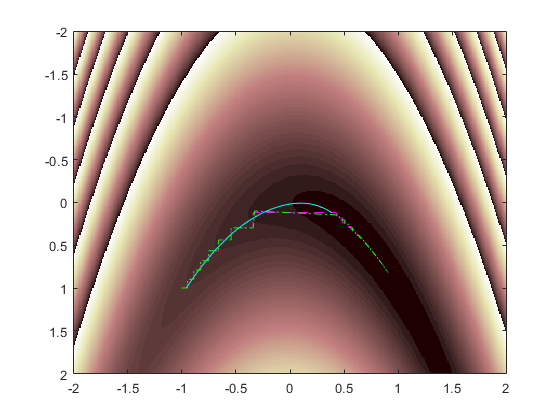

%figure(5);
%imagesc([-2,2],[-2,2],J);
%colormap([pink;pink;pink;pink;pink;pink]);
hold on;
er3 = zeros(1,n);
for k=1:1
    %x=[rand*2-1;rand*2-1];
    x=[-1;1];
    traj=zeros(2,n);
    traj(:,1)=x;
    er3(1)=error(x);
    for i = 1:n-1
        x = gradient_optim(x,g,h);
        traj(:,i+1)=x;
        er3(i+1)=error(x);
    end
    plot(traj(1,:),traj(2,:),'-.g');
end

This method gives almost the same result as relaxation. Because optimal step will stop where the gradient is perpendicular to searching direction

## 3.4

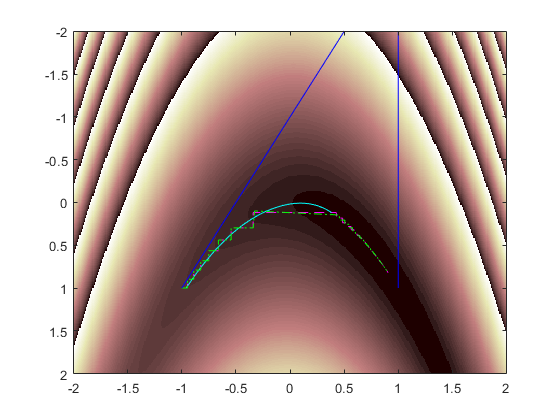

%figure(6);
%imagesc([-2,2],[-2,2],J);
%colormap([pink;pink;pink;pink;pink;pink]);
hold on;
er4 = zeros(1,n);
for k=1:1
    %x=[rand*2-1;rand*2-1];
    x=[-1;1];
    traj=zeros(2,n);
    traj(:,1)=x;
    er4(1)=error(x);
    for i = 1:n-1
        x = newton(x,g,h);
        traj(:,i+1)=x;
        er4(i+1)=error(x);
    end
    plot(traj(1,:),traj(2,:),'b');
end

## 3.5

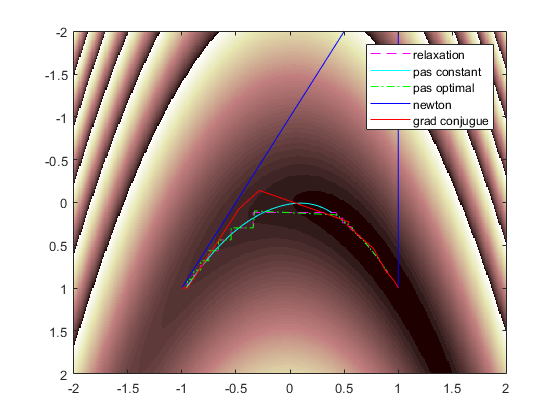

%figure(7);
%imagesc([-2,2],[-2,2],J);
%colormap([pink;pink;pink;pink;pink;pink]);
hold on;
er5 = zeros(1,n);
for k=1:1
    %x=[rand*2-1;rand*2-1];
    x=[-1;1];
    traj=zeros(2,n);
    traj(:,1)=x;
    er5(1)=error(x);
    
    last_gradk = [1;0];
    last_dk = [0;0];
    for i = 1:n-1
        grad = g(x);
        ksi = (grad-last_gradk)'*grad / (last_gradk'*last_gradk);
        dk = grad+ last_dk*ksi;
        if dk'*grad < 0
            dk = grad;
        end
        [x,t] = newton_search(x,dk,g,h);
        last_gradk = grad;
        last_dk = dk;
        traj(:,i+1)=x;
        er5(i+1)=error(x);
    end
    plot(traj(1,:),traj(2,:),'r');
end

legend('relaxation','pas constant','pas optimal', 'newton', 'grad conjugue');

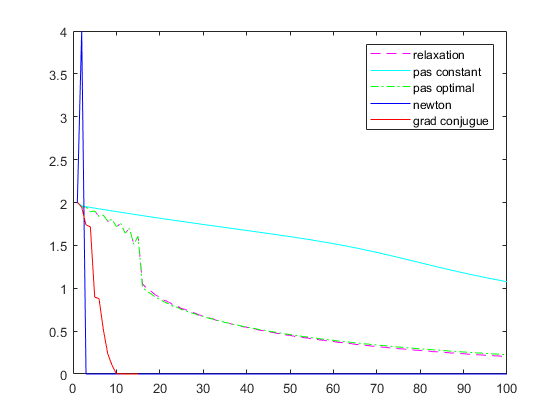

figure(8);
plot(1:n, er1,'--m');
hold on;
plot(1:n, er2, 'c');
plot(1:n, er3, '-.g');
plot(1:n, er4, 'b');
plot(1:n, er5, 'r');
legend('relaxation','pas constant','pas optimal', 'newton', 'grad conjugue');

Constant step method converges very slow because it's simple and naive.

Optimal step and relaxition converges faster, because they search minimum point along one direction. But the choice of direction is naive.

Newton method converge so fast, but it's expensive to inverse a matrix

Conjugate gradient method is also very good, which is not very slow to calculate.